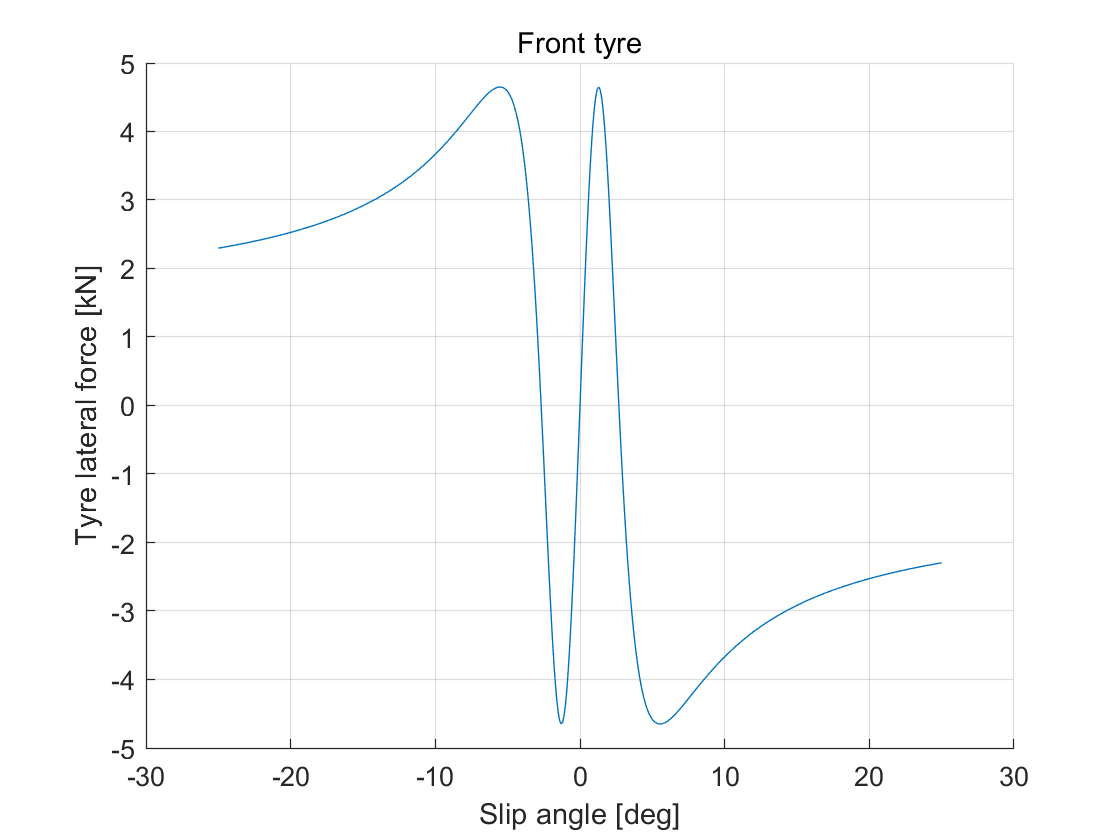

c_f = 20000; % = 1*g*M/deltamax  % front coornering stiffness (C*delta=Fy~M*a)
c_r = 20000; % = 2*g*M/deltamax  % rear coornering stiffness

% Pacejka lateral dynamics parameters
B_f = 18;        % stiffnes factor (Pacejka) (front wheel)
C_f = 3.8;       % shape factor (Pacejka) (front wheel)
D_f = 4650;    % peak value (Pacejka) (front wheel)
E_f = -1.7;     % curvature factor (Pacejka) (front wheel)

a_r = deg2rad(-25:0.1:25);
a_f = deg2rad(-25:0.1:25);
% W_Fy_r = D_f*sin(C_r*atan(B_r*a_r-E_r*(B_r*a_r -atan(B_r*a_r)))); % rear lateral force
W_Fy_f = D_f*sin(C_f*atan(B_f*a_f-E_f*(B_f*a_f -atan(B_f*a_f)))); % front lateral force

figure; hold on; grid on;
plot(rad2deg(a_f),W_Fy_f/1000,'DisplayName','Pacejka tyre model')
% plot(rad2deg(a_f),a_r*c_f/1000,'DisplayName','Constant coornering stiffness model')
title('Front tyre')
xlabel('Slip angle [deg]');
ylabel('Tyre lateral force [kN]')

% legend


